# M E 325 Exam 1 Problem 3

### Group 6

#### Parker Wilson, Preston Witte, Mike Lawlor, Justin Merkel

The loading spectrum for a machine component is shown below. Assume the part has a cross-sectional area of $0\ldotp 1{\textrm{in}}^2$. The fatigue strength $S_f$, of the part's material is 100 kpsi at 50,000 stress cycles and 60 kpsi at ${10}^6$ cycles. The ultimate tensile strength, $S_{\textrm{ut}}$, of the part’s material is 150 kpsi. The single block shown occurs over a time of 5 seconds. Use the Gerber Failure Criterion to determine the value of $\sigma_{e_r }$ .

A = 0.1; % area in^2
S_f_50000 = 100; % kpsi
S_f_1million = 60; % kpsi
S_ut = 150; % kpsi

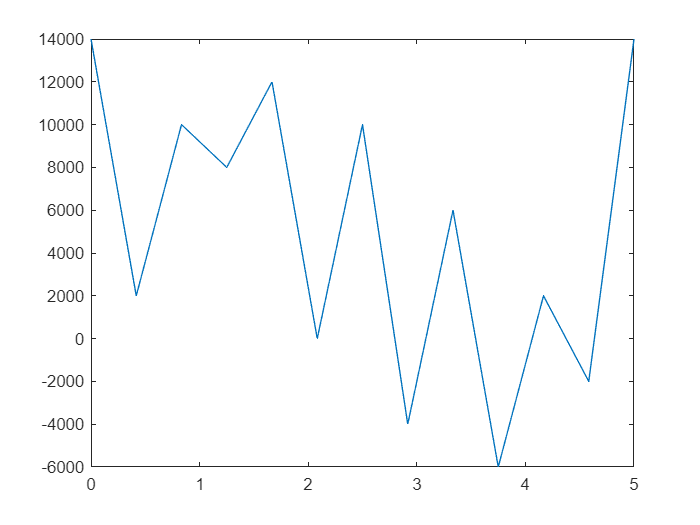



% Plot of loading vs time
x_o = linspace(0,5,13);
y_o = [14000, 2000, 10000, 8000, ...
    12000, 0, 10000, -4000, ...
    6000, -6000, 2000, -2000, 14000];

plot(x_o, y_o)

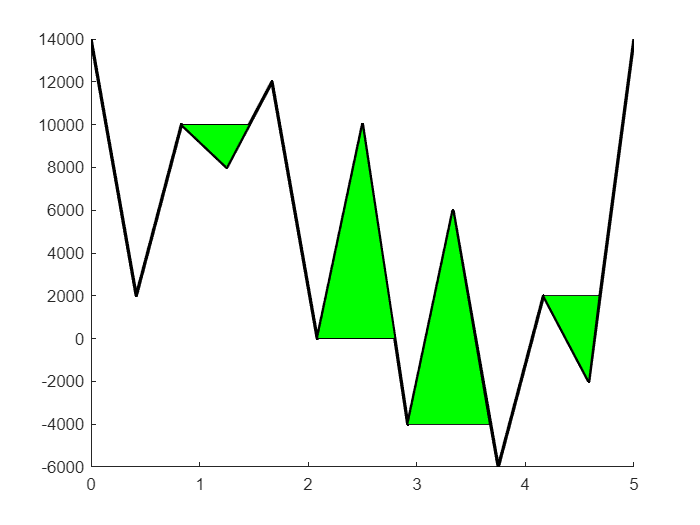

figure;
% Shading of first pass
hold on;
% Curve
plot(x_o, y_o, 'k','LineWidth', 2)

% Cycle #1 shading
x_1 = [x_o(3), x_o(4), (x_o(4)+x_o(5))/2];
y_1 = [y_o(3), y_o(4), y_o(3)];
fill(x_1, y_1, 'g');

% Cycle #2 Shading
x_2 = [x_o(6), x_o(7), 2.8];
y_2 = [y_o(6), y_o(7), y_o(6)];
fill(x_2, y_2, 'g');

% Cycle #3 shading
x_3 = [x_o(8), x_o(9), 3.67];
y_3 = [y_o(8), y_o(9), y_o(8)];
fill(x_3, y_3, 'g');

% Cycle #4 shading
x_4 = [x_o(11), x_o(12), 4.68];
y_4 = [y_o(11), y_o(12), y_o(11)];
fill(x_4, y_4, 'g');

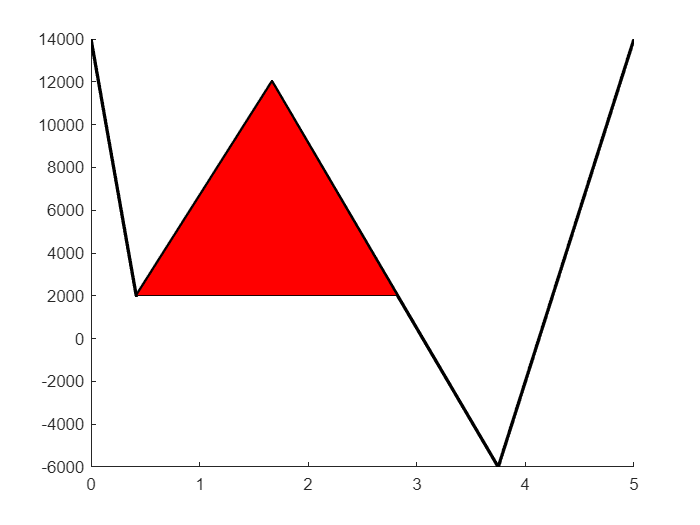

figure;

% Shading of second pass
% Curve
x_2nd = [x_o(1), x_o(2), x_o(5), x_o(10), x_o(13)];
y_2nd = [y_o(1), y_o(2), y_o(5), y_o(10), y_o(13)];
hold on;
plot(x_2nd, y_2nd, 'k', LineWidth=2);

% Cycle #5 Shading
x_5 = [x_2nd(2), x_2nd(3), 2.82];
y_5 = [y_2nd(2), y_2nd(3), y_2nd(2)];
fill(x_5, y_5, 'r');

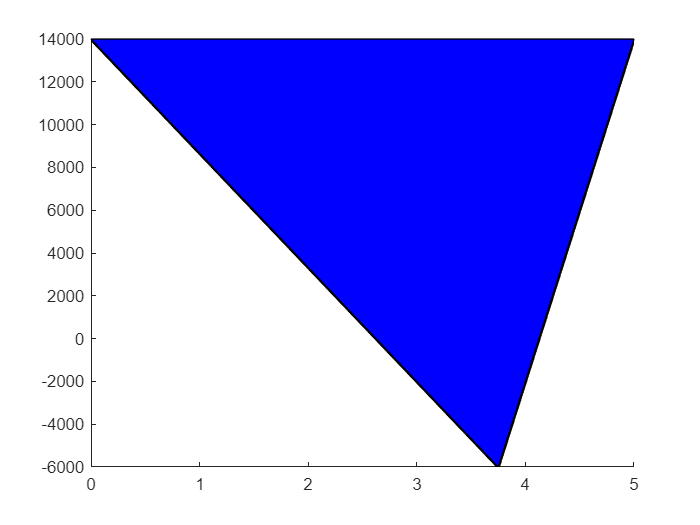

figure;

% Shading of third pass
x_3rd = [x_2nd(1), x_2nd(4), x_2nd(5)];
y_3rd = [y_2nd(1), y_2nd(4), y_2nd(5)];
hold on;
plot(x_3rd, y_3rd, 'k', LineWidth=2);

% Cycle #6 Shading
fill(x_3rd, y_3rd, 'b');


figure;


Determine Basquin Parameters (from sf values)

% Create an augmented matrix for the linearized system of equations for the
% basquin parameters
Aug = [1 log10(50000) log10(S_f_50000); ...
       1 log10(1e6) log10(S_f_1million)]

Aug =     1.0000    4.6990    2.0000
    1.0000    6.0000    1.7782



% convert augmented matrix to reduced row echelon form
reduced = rref(Aug)

reduced =     1.0000         0    2.8013
         0    1.0000   -0.1705


a = 10^reduced(1, 3)

a = 632.7876

b = reduced(2, 3)

b = -0.1705